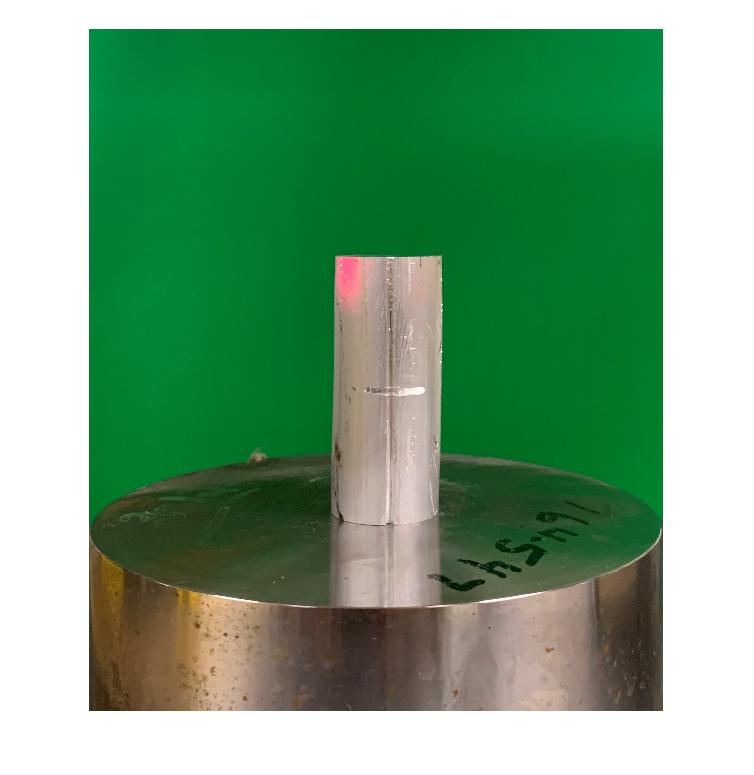

%gaussian_blur
image = imread('1.jpg');
figure(1),
imshow(image);

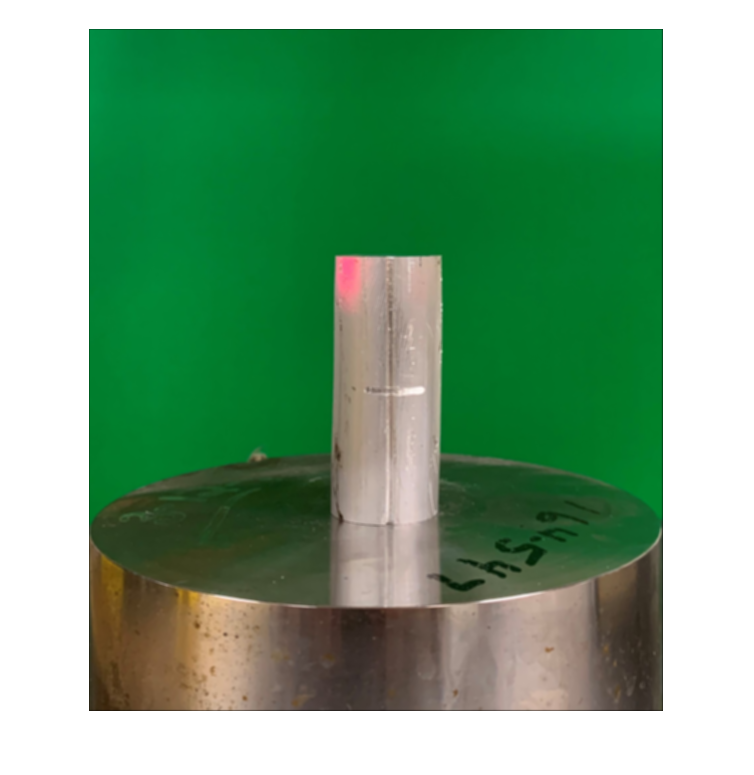

w=fspecial('gaussian',[10 10],5);
im=imfilter(image,w);
figure(2),
imshow(im);

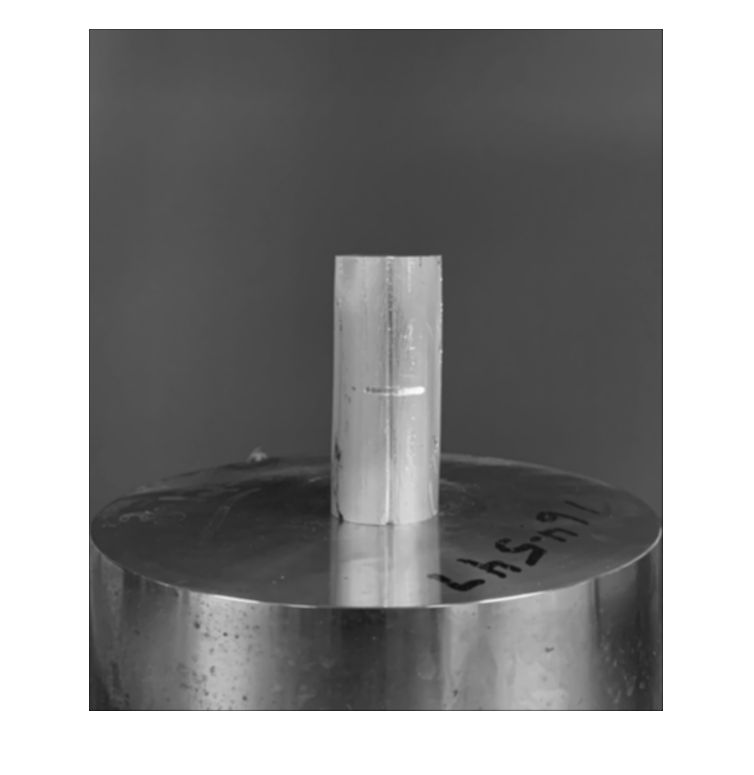



%gray_image 
% Convert to gray scale
gray = (0.2989 * double(im(:,:,1)) + ...
        0.5870 * double(im(:,:,2)) + ...
        0.1140 * double(im(:,:,3)))/255;

figure();
imshow(gray);

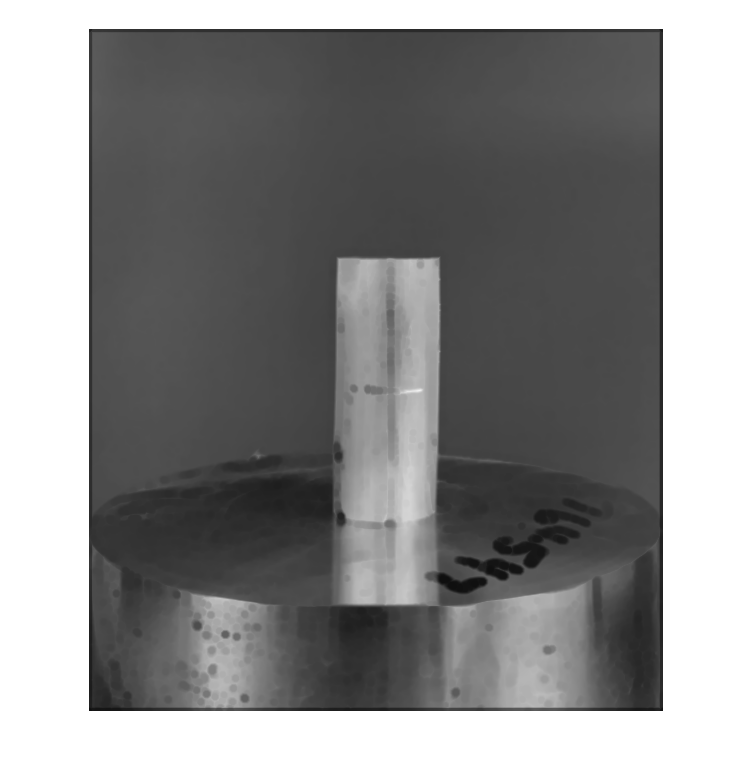


A1=gray;
%erosion
se1=strel('disk', 8);%这里是创建一个radius为8的平坦型圆盘结构元素
A2=imerode(A1,se1);
imshow(A2);

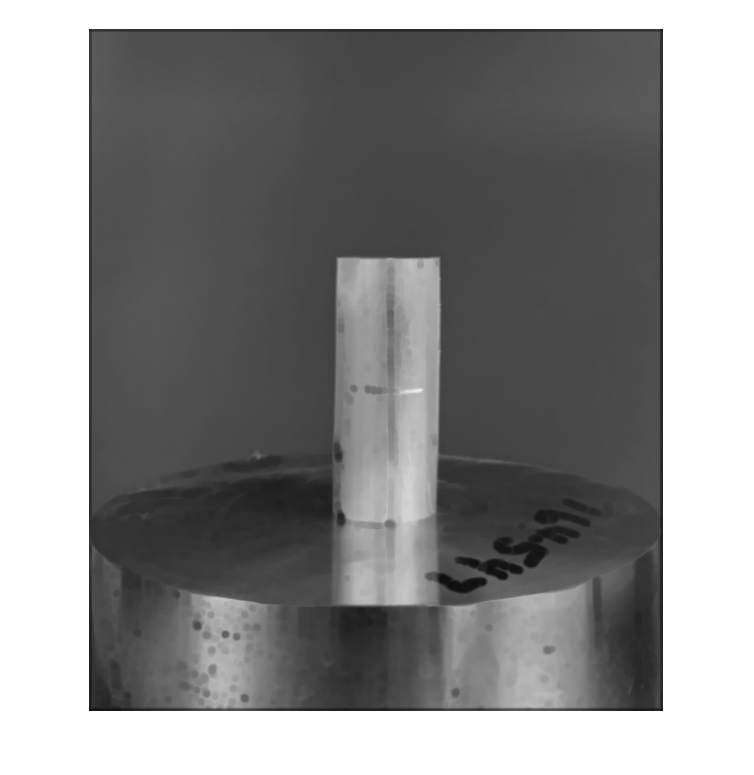


%dilation
B=[0 8 0
      8 8 8
      0 8 0];
A3=imdilate(A2,B);
imshow(A3);

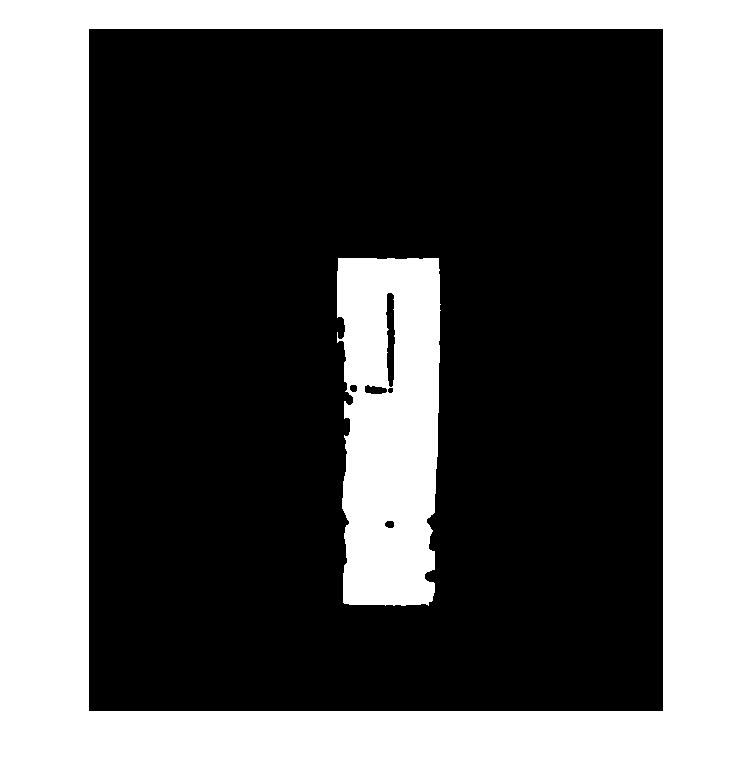




%Find the largest connected domain
img=A3;
img=im2bw(img);  
imLabel = bwlabel(img);                %Mark each domain  
stats = regionprops(imLabel,'Area');    %Find the size of each connected domain 
area = cat(1,stats.Area);  
index = find(area == max(area));        %Find the area of the largest connected domain  
img1= ismember(imLabel,index);          %Obtain the largest connected domain image 
figure(2)  
imshow(img1);

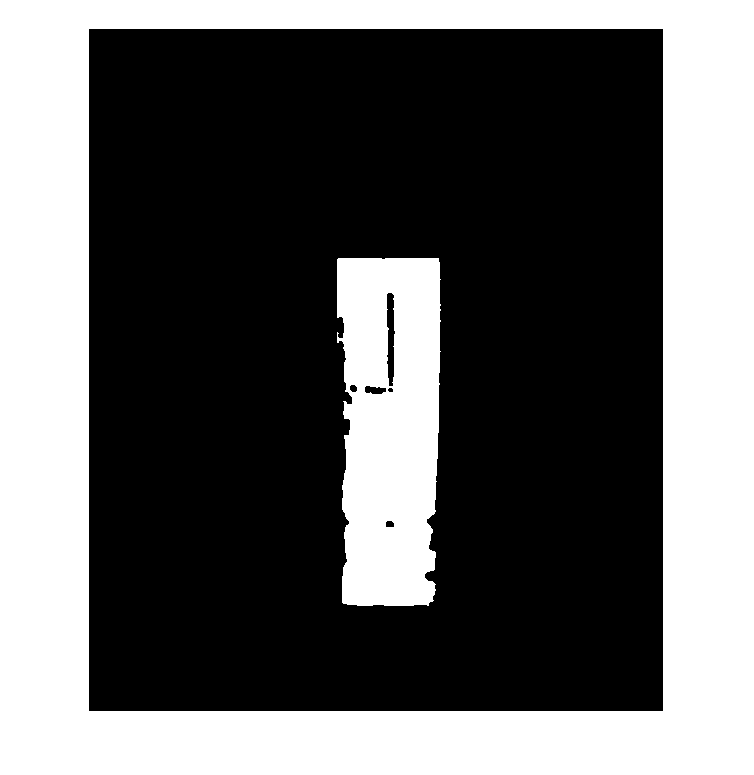


%dilation
B=[0 8 0
      8 8 8
      0 8 0];
BW2=imdilate(img1,B);
imshow(BW2);

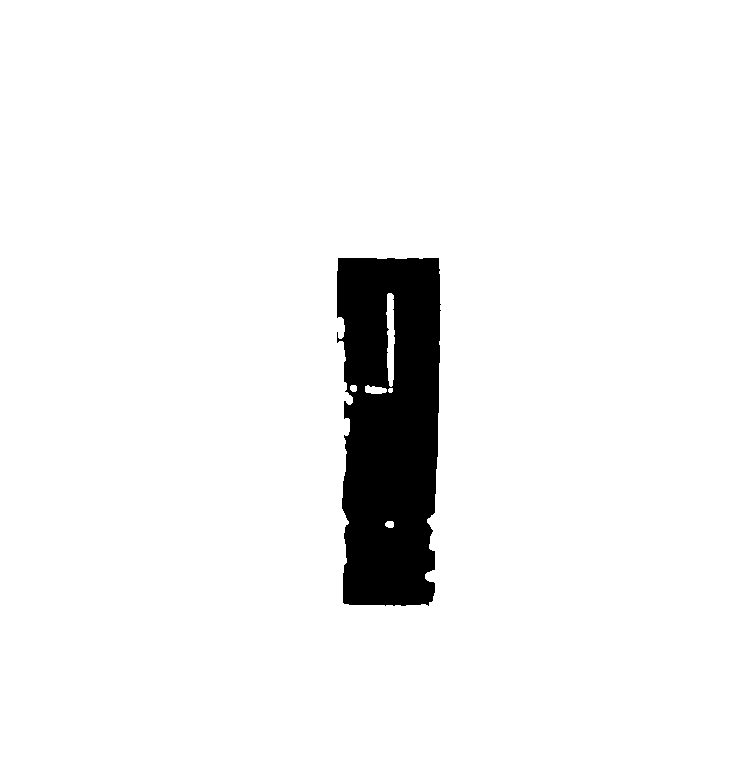


img1_reverse = imcomplement(img1);imshow(img1_reverse);

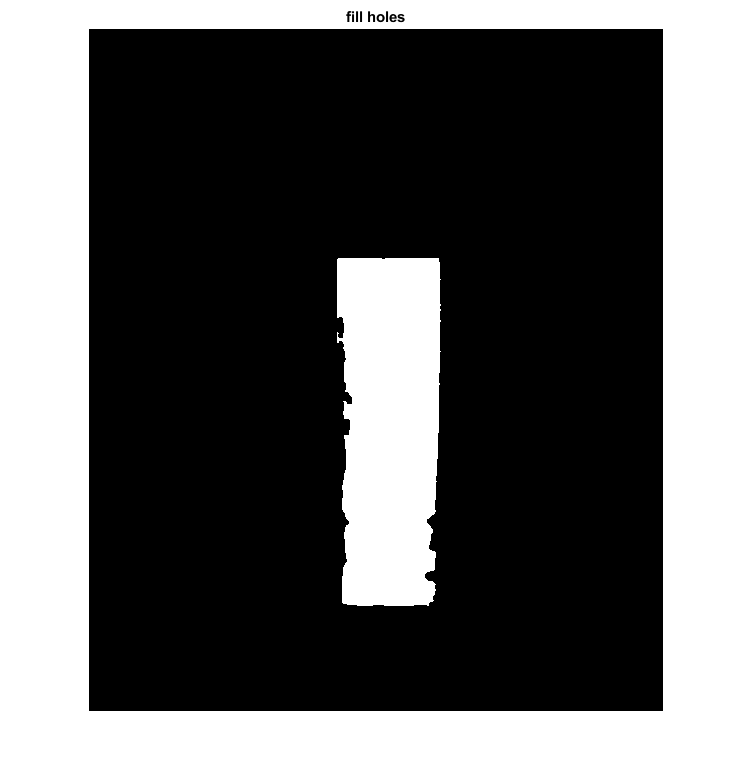


%fill holes
img1=BW2;
I1=imfill(img1,'holes');            
imshow(I1);title('fill holes');

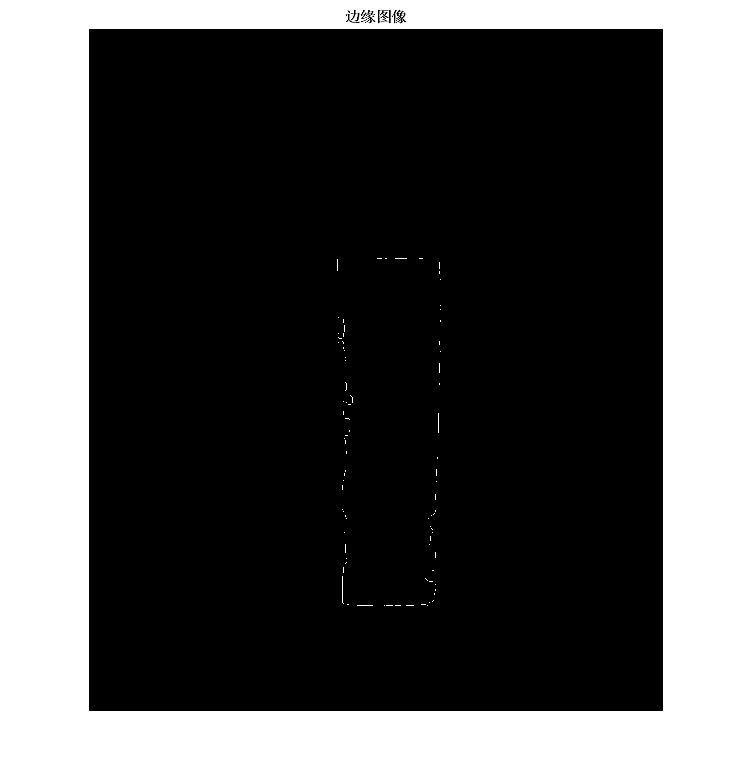

% 提取最外围边缘
I2=bwperim(I1);                   
imshow(I2); title('边缘图像');

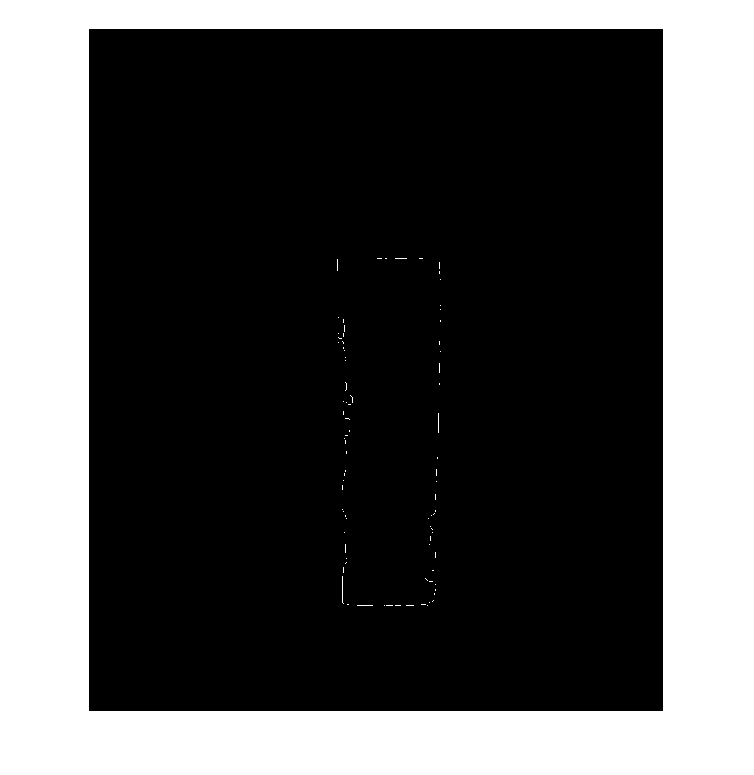

% Remove objects with an area less than 1500px
I3=bwareaopen(I2,1500);    
figure(6),imshow(I3);

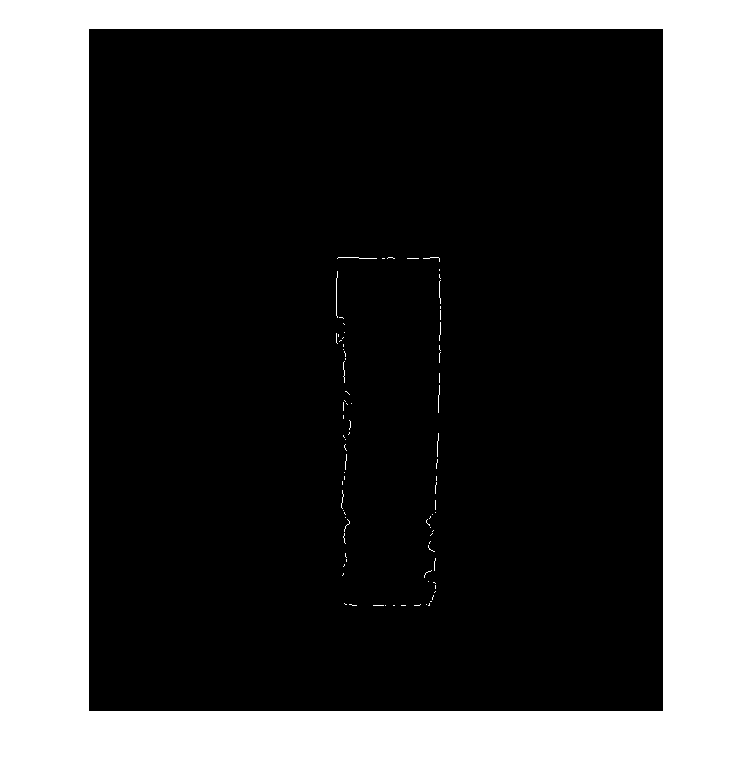


%edge detection
BW1 = edge(I3,'sobel',0.3);
imshow(BW1);

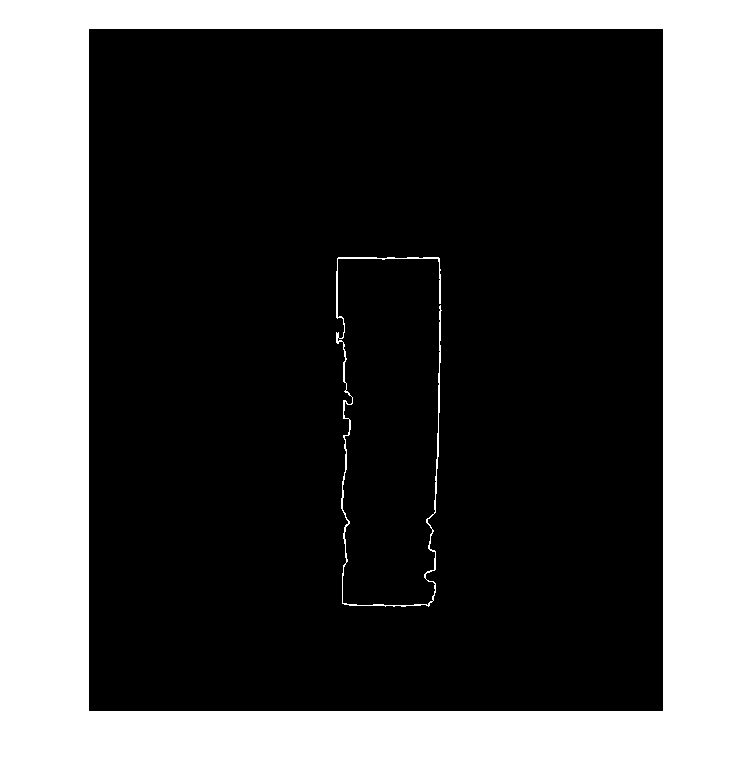

%dilation
B=[0 8 0
      8 8 8
      0 8 0];
BW2=imdilate(BW1,B);
imshow(BW2);

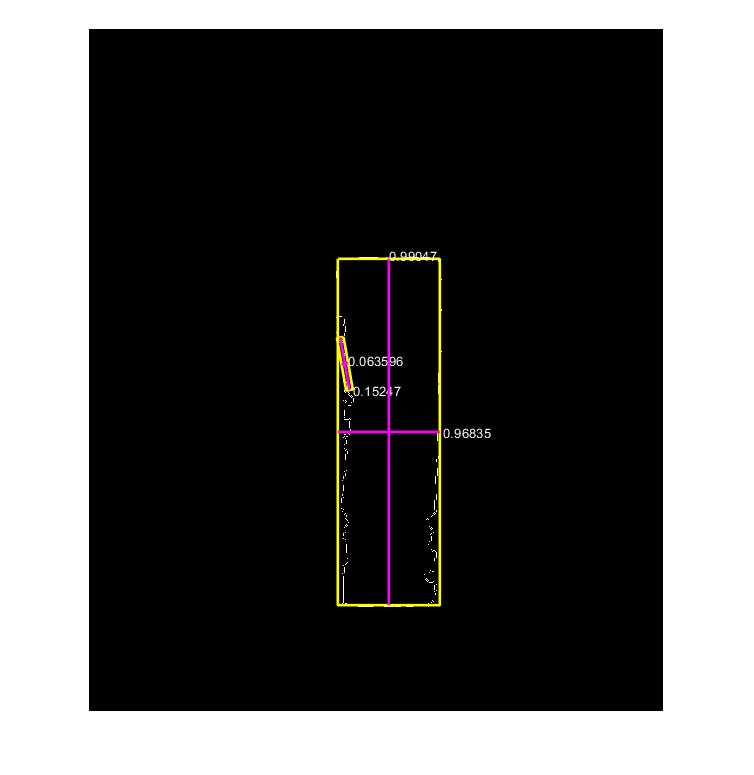


BW3 = edge(BW2,'sobel',0.3);
imshow(BW3);





I5=BW3;
coin_width=1.000;
coin_height=1.000;
[labelpic,num] = bwlabel(I5,8);  % 标记
[r c]=find(labelpic==1);
% 获取标记物体最小外接矩形坐标点
[rectx,recty,area,perimeter] = minboundrect(c,r,'p');   
% 计算最小外接矩形长宽
[length width] = minboxing(rectx(1:end-1),recty(1:end-1));
%figure(7),imshow(I5);%hold on

 pixels_length_rate=length/coin_height;
 pixels_width_rate=width/coin_width;

 midpointx=zeros(2,2);
 midpointy=zeros(2,2);
 target_mat=zeros(1,num);
 
 
 
 for v=2:num
    [r c]=find(labelpic==v);
    [rectx,recty,area,perimeter]=minboundrect(c,r,'p');
    [length width] = minboxing(rectx(1:end-1),recty(1:end-1));
     % Draw the target detection frame
    line(rectx,recty,'color','y','linewidth',2);
             midpointx(1)=(rectx(1)+rectx(2))/2;
             midpointx(2)=(rectx(3)+rectx(4))/2;
             midpointx(3)=(rectx(2)+rectx(3))/2;
             midpointx(4)=(rectx(4)+rectx(1))/2;

             midpointy(1)=(recty(1)+recty(2))/2;
             midpointy(2)=(recty(3)+recty(4))/2;
             midpointy(3)=(recty(2)+recty(3))/2;
             midpointy(4)=(recty(4)+recty(1))/2;
      % Draw the line between the midpoints of the target length and width
     line(midpointx,midpointy,'color','m','linewidth',2);
     target_float_length=length/pixels_length_rate;
     target_length=num2str(target_float_length);
     target_float_width=width/pixels_width_rate;
     target_width=num2str(target_float_width);
     
     % Display length and width
     if((rectx(2)-rectx(1))<=(recty(2)-recty(1)))
         text(midpointx(1),midpointy(1)-10,target_length,'Color','white');
         text(midpointx(3)+10,midpointy(3),target_width,'Color','white');
     else
         text(midpointx(1),midpointy(1)-10,target_width,'Color','white');
         text(midpointx(3)+10,midpointy(3),target_length,'Color','white');
     end
 end